# The ds9 static class

# in the astronomy & astrophysics toolbox for MATLAB

## Description:

The `ds9` is a static class to support interaction with the [ds9 astronomical images viewer](http://ds9.si.edu/site/Home.html). This file is accessible through the `manual` package (i.e. `manual.ds9`). See also the [FITS static class](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/FITS.html), and the [SIM class](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/SIM.html).

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

In addition use of this class require to install ds9 and the XPA messaging system:

[ds9 intellation and instructions](http://ds9.si.edu/site/Download.html)

[XPA instellation](http://ds9.si.edu/site/XPA.html)

Note about XPA

MATLAB is communicaing with ds9 via the XPA messaging system. For more information see: [XPA documentation and instruction set](http://ds9.si.edu/doc/ref/xpa.html).

# Methods and examples

To see all the `ds9` methods type "`ds9.`" followed by <tab>. Detailed help is available for each function using the help or doc coomands:hh

help ds9.sdssnavi

 ------------------------------------------------------------------------------
  sdssnavi function                                                        ds9
  Description: Click on a position in an image displayed in ds9 and this
               program will open the SDSS navigator web page for the
               coordinates.
  Input  : - Broweser type:
             'browser' - existing system browser (default).
             'new'     - Matlab internal browser.
  Output : - J2000.0 RA of position [radians].
           - J2000.0 Dec of position [radians].
           - Link to SDSS navigator.
  Required: XPA - http://hea-www.harvard.edu/saord/xpa/
  Tested : Matlab 7.11
      By : Eran O. Ofek                    May 2011
     URL : http://weizmann.ac.il/home/eofek/matlab/
  Example: [RA,Dec,Link]=ds9.sdssnavi;
  Reliable: 2
 -----------------------------------

## Low level commands

For more advance users it may be useful sometimes to send some commands directly to ds9. You can use the commands `ds9.system`, `ds9.construct_command`, `ds9.xpaset`, `ds9.xpaget`, `ds9.xpahelp`.

## Open ds9

Use ds9.open to open the ds9 display:

ds9.open

eran     45792  0.3  0.0 139816 39008 pts/39   S    13:39   0:06 ds9
ds9 is already open


while you can check if the ds9 dsiplay is open using:

ds9.isopen

eran     45792  0.3  0.0 139816 39008 pts/39   S    13:39   0:06 ds9


ans =    1


and you can close the ds9 display using the `ds9.exit` command.

## Display images

You can use the `ds9` command to display an image in ds9 from matlab (the ds9 command is in fact the ds9 class constructor). The `ds9` command can display images in stored in many formats (e.g., FITS file names, matrix, cubes, `SIM` objects). For example:

cd ~/matlab/images/
ds9('test_PTF*.fits');

eran     13476  0.0  0.0 148960 48256 pts/39   S    Feb13   0:59 ds9
ds9 is already open


The `ds9` command first check if there is an open ds9 window. If there is one, then the images will be displayed in the existing window, and if not it will opend a ds9 window and display the images. Each image will be displayed in its own frame.

You can also display matrix:

ds9(rand(100,100))

eran     45792  6.9  0.0 205168 104356 pts/39  S    13:39   0:02 ds9
ds9 is already open


or a `SIM` object

S=FITS.read2sim('test_PTF*.fits');
ds9(S)

The result of the last command:

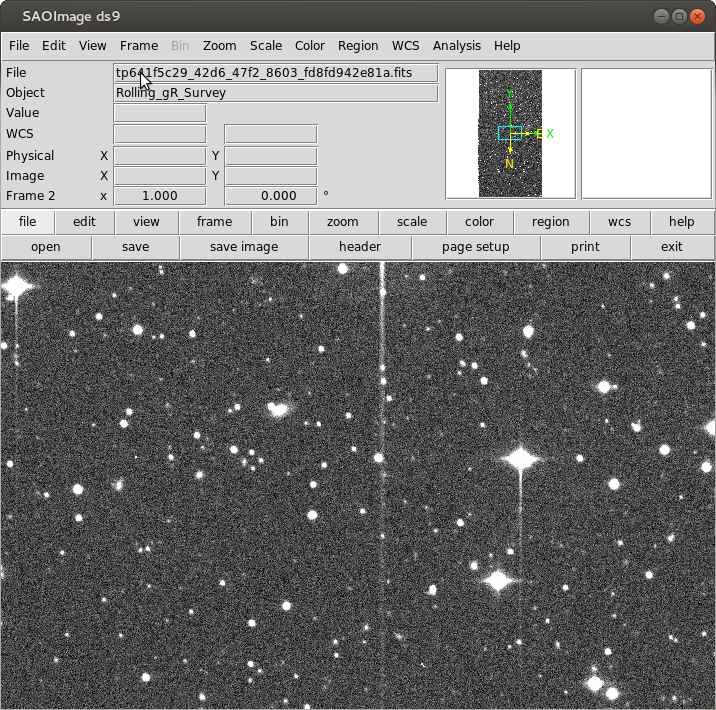

Other options are available (e.g., list of files, cell array). See `Util.files.create_list` for additional options.

The ds9 command uses internally the ds9.disp command so additional options type: 

help ds9.disp

You can control some of the dsiplay properties. For example, display an image into the next frame:

ds9(S(1),'next')

eran     45792  1.2  0.0 205168 104356 pts/39  S    13:39   0:04 ds9
ds9 is already open


or display images into some buffers and change the zoom factor and colorbar setting:

ds9(S,[2 1],'Zoom',0.25,'Colorbar','yes')

eran     45792  1.1  0.0 205192 104380 pts/39  S    13:39   0:04 ds9
ds9 is already open


Another related functions are `ds9.load, ds9.load1,` and `ds9.url`.

All the options available in the `ds9` command (e.g., controling the scale, zscale, colormap, etc.) are also available as stand alone functions.

The ds9.frame command allow you to control the frame number.

For example:

% return the current frame number
ds9.frame

ans = 1


% set the current frame to frame number 2
ds9.frame(2)
% set the frame to the first frame
ds9.frame('first')

You can also clear a frame by:

% clear current frame
ds9.clear_frame
% clear the second frame
ds9.clear_frame(2)

or delete a frame:

ds9.delete_frame(2)

## Control the display

You can control the scale, colormap, colorbar, orientation, pan, rotation and zoom via the `ds9.scale, ds9.cmap, ds9.colorbar, ds9.orient, ds9.pan, ds9.rotate, and ds9.zoom`, respectively.

Example:

ds9.disp('test_PTF*.fits');

eran     45792  0.2  0.0 204816 104008 pts/39  S    13:39   0:09 ds9
ds9 is already open


ds9.frame(1)
ds9.zoom(0.25)
ds9.rotate(45)

Note that in many of these functions there is a distinction between the absolute value and relative value. For example, zoom relative to current zoom and absolute zoom.

For exampe:

ds9.delete_frame(Inf) % delete all frames
ds9.disp('test_PTF*.fits');

eran     45792  0.3  0.0 137476 36796 pts/39   S    13:39   0:13 ds9
ds9 is already open


ds9.frame(1)        % absolute zoom
ds9.zoom('2')       % relative zoom
ds9.zoom('to 0.2')  % another way to indicate absolute zoom

The ds9.tile command can be used to control tile options:

ds9.tile([1 2])  % dispaly two tiles in a raw

You can match the properties of all frames to that of the current frame using the `ds9.match_wcs, ds9.match_xy, ds9.match_scale, `and` ds9.match_scalelimits` commands. You can also lock the properties of the frames in respect to each other using the `ds9.lock_wcs`, and `ds9.lock_xy` commands.

To print the current frame into a PostScript file:

ds9.psprint('FileName.ps')

## Pixel data

In order to load the current ds9 image into matlab as a SIM object:

S=ds9.read2sim

S =   SIM with properties:

               Im: [4096×2048 double]
    ImageFileName: '/tmp/tpe2b1f8e7_8db7_4156_b62c_271e8cfc45ab'
           BackIm: []
            ErrIm: []
         WeightIm: []
              Cat: []
              Col: []
          ColCell: []
         ColUnits: []
         SortedBy: []
      SortedByCol: []
             Name: []
           Source: []
        Reference: []
          Version: []
           Header: {374×3 cell}
              WCS: []
         UserData: []
             Mask: []
          MaskDic: []
              PSF: []
           ErrPSF: []
           ParPSF: {}
           CooPSF: []


You can also read a box region into a matrix:

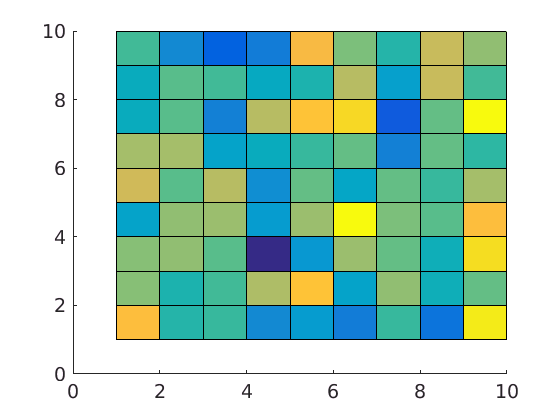

[MatV,MatX,MatY]=ds9.getbox([101 110 101 110]);
surface(MatV)

## Header

You can visualize the FITS imager header using:

ds9.header

## Overlay plots and region files

A powerful property of ds9 is the ability to overlay symbols and text on the display. The function` ds9.load_region,ds9.save_region` and `ds9.delete_region `can be used to load existing ds9 region file, save a region file, and delete regions from the display, respectivelly.

The function ds9.write_region can be use to generate and write region files (but not load). The function has many options and it is recomended to read its help:

help ds9.write_region

Likely the most useful function is the `ds9.plot` command. The `ds9.plot `can call the `ds9.write_region` and `ds9.load_region.`

`Examples:`

ds9('test_PTF*.fits');

eran     45792  0.2  0.0 208844 107376 pts/39  S    13:39   0:21 ds9
ds9 is already open


ds9.tile([1 1])
ds9.zoom(0.2)
% plot a red circle in X=1000 Y=2000
ds9.plot(1000,2000)

You can use the `ds9.plot` command in many different ways and here we present only some of them:

X=rand(100,1).*2000;
Y=rand(100,1).*4096;
% plot blue squares around some random points
ds9.plot(X,Y,'bs')

The coordinate can be also an `AstCat` or `SIM` objects:

% read FITS images into a SIM object
S=FITS.read2sim('test_PTF*.fits');
S=S(1);
% find sources and generate a acatalog in the SIM object
S=mextractor(S);

  Set gain to 1
mextractor first pass - Constructing optimal PSF
  Set gain to 1
  No filter found - Use DefFilter
  Estimate images background and std


  Subtract background
  Filter image number 1 - use 1 filters
    Threshold image and locate local maxima
    Extracting 4349 sources
  Calculate 1st and 2nd moments


mextractor second pass - Source detection and measurments
  Subtract background


  Filter image number 1 - use 2 filters
    Threshold image and locate local maxima
    Extracting 7430 sources
  Calculate 1st and 2nd moments
    Calculate PSF photometry
    Calculate IL aperture photometry (using aper_phot)


% plot all the entries in the catalog (sources) as white circles.
ds9(S)

eran     45792  0.2  0.0 208844 107384 pts/39  S    13:39   0:22 ds9
ds9 is already open


ds9.plot(S,'wo')

You can control the symbol shape size and coordinate format (see ds9.write_region help for details). For example:

S=FITS.read2sim('test_PTF*.fits');
S=S(1);
[RA,Dec]=xy2coo(S,1000,2000);
ds9.plot(RA,Dec,'ro','Width',2,'Size',100,'Text','Hello','FontSize',20,'Coo','fk5','Units','rad');

Some other useful function to plot lines are `ds9.line_x`y and `ds9.line_lt`:

ds9.line_xy([356 400],[2000 2100],'Color','green')
ds9.line_lt([400,450],[1900,1910],[100,200],[10,45])

Finally you can write text:

S=FITS.read2sim('test_PTF*.fits');
S=S(1);
[RA,Dec]=xy2coo(S,1000,2000);
RA=celestial.coo.convertdms(RA,'r','SH');
Dec=celestial.coo.convertdms(Dec,'R','SD');
ds9.text(RA,Dec,'Object','color','blue')
% or
ds9.text(1000,2200,'Hello');

## Interactive examination

The ds9 class provide several function for interactive tools for the ds9 display.

`ds9.imexam`

The `ds9.imexam` function allows for interactive ds9 image examination, including flux cuts, aperture and PSF photometry, radial plot, surface plot, contour plot, moments, background estimation, and interaction with the SIM object and its catalog.

`ds9.imexam` is designed in the spirit of `IRAF imexam`.

Example:

ds9('test_PTF*4162_c08.fits');

eran     45792  0.0  0.0 215004 114192 pts/39  S    Jan17   0:43 ds9
ds9 is already open


Res=ds9.imexam;


Click h for help, q to abort

 --- ds9.imexam Menu:
q   - Abort
h   - This help
Left mouse click - recenter on mouse click
Arrows - move cursor
v   - Plot vector cut between 2 points
x,j - Plot vector cut along x axis
y,i - Plot vector cut along y axis
s   - Surface plot around point
c   - Countour plot around point
m   - First and second moments
r   - Radial profile with centering
R   - Radial profile without centering
a   - Aperture photometry with centering
A   - Aperture photometry without centering
p   - PSF photometry with centering
P   - PSF photometry without centering
b   - Estimate local background and noise
S   - Return the nearest source found using mextractor
e   - Edit/set parameters (and show help for editing)

Click h for help, q to abort

 --- ds9.imexam Menu:
q   - Abort
h   - This help
Left mouse click - recenter on mouse click
Arrows - move cursor
v   - Plot vector cut between 2 points
x,j - Plot vector cut along x axis
y,i - Plot vector cut along y axis
s   - Surf

% The ds9 cursor is now blinking and you are ready to inspect the image.
% you can click some mouse or keyborad keys while the cursor
% hover over the ds9 display.
% Type "h" to see the interactive options

After clicking "h" the following shotr help section will appear in the matlab screen:

% --- ds9.imexam Menu:
% q   - Abort
% h   - This help
% Left mouse click - recenter on mouse click
% Arrows - move cursor
% v   - Plot vector cut between 2 points
% x,j - Plot vector cut along x axis
% y,i - Plot vector cut along y axis
% s   - Surface plot around point
% c   - Countour plot around point
% m   - First and second moments
% r   - Radial profile with centering
% R   - Radial profile without centering
% a   - Aperture photometry with centering
% A   - Aperture photometry without centering
% p   - PSF photometry with centering
% P   - PSF photometry without centering
% b   - Estimate local background and noise
% S   - Return the nearest source found using mextractor
% e   - Edit/set parameters (and show help for editing)
% 
% Click h for help, q to abort

For example, you can move the cursor over a star and click "r" - this option will extract the region ariound the source, calculate its first moment and calculate a radial profile centered around the center of light. In addition some information will be displayed on the matlab screen. The "S" option will run SIM/mextractor to generate a source catalog and allow you to interactively inspect the catalog for the nearest source.

Many of the options have some free parameters (e.g., extraction radius, or aperture photometry diameter). You can set the value of these parameters using the key,val options, or epar command, or interactivel usinf the "e" interactive option. The later will ask you to write to the matlab screen the parameter value to use (e.g., "Radius=10"). See `ds9.imexam` help for details.

`ds9.imexam` also return a structure array (element per click) that contains all the retrieved data. For example, for the "r" option it will also return the values of the radial plot.

**Additional interactive functions**

The `ds9.ginput` function allow you to click on the ds9 display and get the X/Y or RA/Dec coordinates as well of the pixel value at the clicked position

`ds9.getpos` is a special case of ds9.ginput for X/Y positions only, while ds9.getcoo is for RA/Dec coordinates.

`ds9.imark` can be use dor interactively ploting symbols in ds9, `ds9.iline `for plotting lines, and `ds9.ipoly` for plotting polygons.

In response to a click on the ds9 display, the `ds9.sdssnavi` open a browser with the [SDSS navigator](http://skyserver.sdss.org/dr13/en/tools/chart/navi.aspx) for the clicked sky position.

`ds9.nearestcat` return the nearest source in a SIM object to the clicked position, while `ds9.nearcat `return all sources within a search radius.

`ds9.simval` can be used to get the SIM object images values for the clicked position.

To blink between ds frames you can use `ds9.blink`.